close all
clear
clc

## C.1.2.2 Plucker coordinates

P = [2 3 4]'; Q = [3 5 7]';

L = Plucker(P, Q)

 
L = 
{ 1  -2  1; -1  -2  -3 }



L.v'

ans =      1    -2     1


L.w'

ans =     -1    -2    -3


L.L

ans =      0     1     2    -1
    -1     0     1    -2
    -2    -1     0    -3
     1     2     3     0


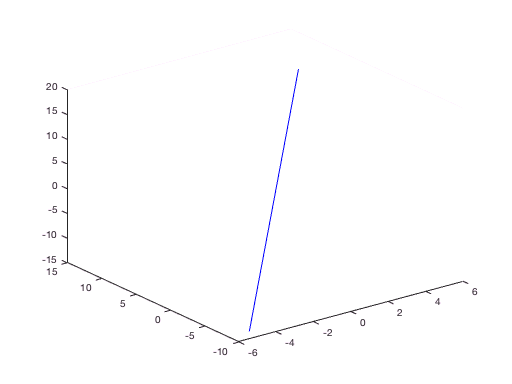


%L.coords

axis([-5 5 -5 5 -5 5]);
L.plot('b');

L.point([0 1 2])

ans =    -0.5714   -1.5714   -2.5714
   -0.1429   -2.1429   -4.1429
    0.2857   -2.7143   -5.7143



[x, d] = L.closest([1 2 3]')

x =     3.1381
    2.5345
    1.9310


d = 2.4495


L.plane_intersect([0 0 1 0])'

ans =     0.6667    0.3333         0


## C.1.4.1 Ellipse properties

E = [2 -1; -1 1];

clf
plot_ellipse(E)

[x,e] = eig(E)

x =    -0.5257   -0.8507
   -0.8507    0.5257


e =     0.3820         0
         0    2.6180



r = sqrt(diag(e))

r =     0.6180
    1.6180


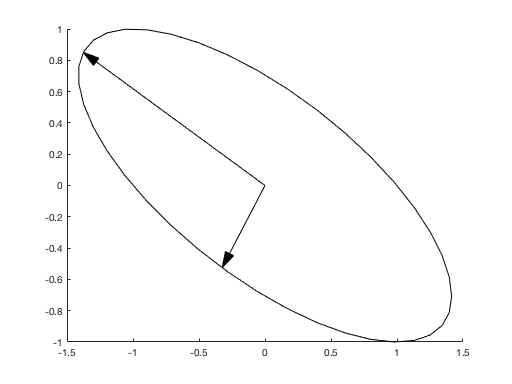


arrow([0 0]', x(:,1)*r(1));
arrow([0 0]', x(:,2)*r(2));


atan2(x(2,2), x(1,2)) * 180/pi

ans = 148.2825

## C.1.4.2 drawing an ellipse

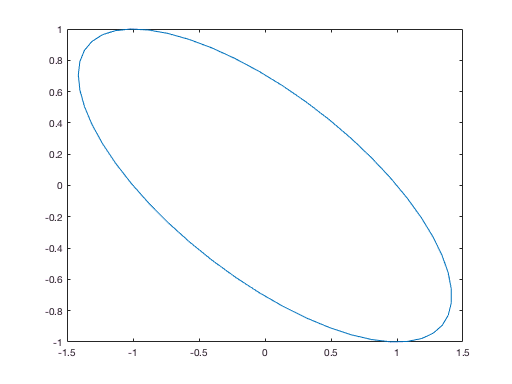

E = [2 -1; -1 1];

th = linspace(0, 2*pi, 50);
y = [cos(th);  sin(th)];

x = (sqrtm(E) * y)';
plot(x(:,1), x(:,2));

## C.1.4.3 fitting to an ellipse

randinit
clf

% generate a set of points within the ellipse
p = [];
while true
    x = (rand(2,1)-0.5)*4;
    if norm(x'*inv(E)*x) <= 1
        p = [p x];
    end
    if numcols(p) >= 500
        break;
    end
end
plot(p(1,:), p(2,:), '.')

% compute the moments
m00 = mpq_point(p, 0,0);
m10 = mpq_point(p, 1,0);
m01 = mpq_point(p, 0,1);
xc = m10/m00; yc = m01/m00;

% compute second moments relative to centroid
pp = bsxfun(@minus, p, [xc; yc]);

m20 = mpq_point(pp, 2,0);
m02 = mpq_point(pp, 0,2);
m11 = mpq_point(pp, 1,1);

% compute the moments and ellipse matrix
J = [m20 m11; m11 m02];
E_est = 4 * J / m00

E_est =     1.8706   -0.9151
   -0.9151    0.9716



E_est

E_est =     1.8706   -0.9151
   -0.9151    0.9716


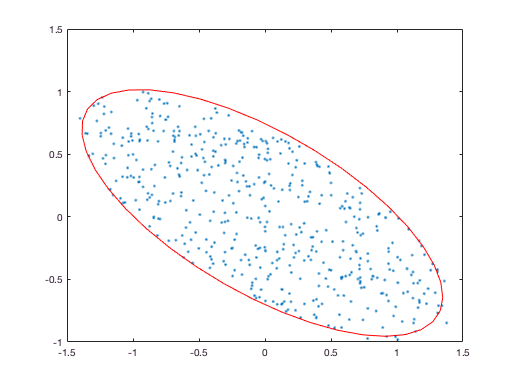

plot_ellipse(E_est, [xc yc],  'r')

## C.2.1 2D

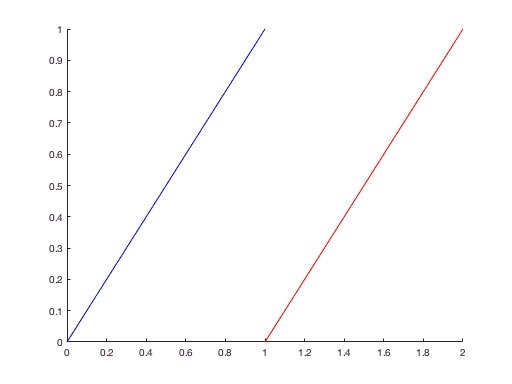

l1 = [1 -1 0]';
l2 = [1 -1 -1]';

clf  % DIFF
plot_homline(l1, 'b')
plot_homline(l2, 'r')


cross(l1, l2)

ans =      1
     1
     0
